# Brain Immune test

input_path = 'E:\Brain_slice_0302\';
dims = [3072 3072 136 4 6];

useGPU = true;

curr_gpu = gpuDevice();
org_run = new_STARMapDataset(input_path, dims, 'useGPU', useGPU);
org_run = org_run.LoadRawImages;

new_run = org_run;

% new_run.rawImages = new_run.rawImages(1:1024, 1:1024, 1:34, :,:);
% new_run.rawImages = new_run.rawImages(1:1024, 1:1024, 35:68, :,:);
new_run.rawImages = new_run.rawImages(1:1024, 1:1024, 69:102, :,:);
% new_run.rawImages = new_run.rawImages(1:1024, 1:1024, 103:136, :,:);

new_run.rawImages = gpuArray(new_run.rawImages);
new_run = new_run.LoadCodebook;
new_run = new_run.SwapChannels;
new_run = new_run.MinMaxNormalize;  
new_run = new_run.MorphoRecon;
new_run = new_run.GlobalRegistration;
new_run = new_run.LocalRegistration('Iterations', 10);

new_run = new_run.SpotFinding('Method', "max3d", 'qualityThreshold', 0.01, 'volumeThreshold', 1, 'showPlots', true);
new_run = new_run.ReadsExtraction('showPlots',false); 
new_run = new_run.ReadsFiltration('showPlots',false);

nissl_path = 'E:\Brain_slice_0302\nissl\nissl_max_tile_3.tif';
nissl_img = imread(nissl_path);

figure
imshow(nissl_img)
hold on 
plot(new_run.goodSpots(:,1), new_run.goodSpots(:,2), 'ro', "Color", 'red', "MarkerSize", 2)
hold off

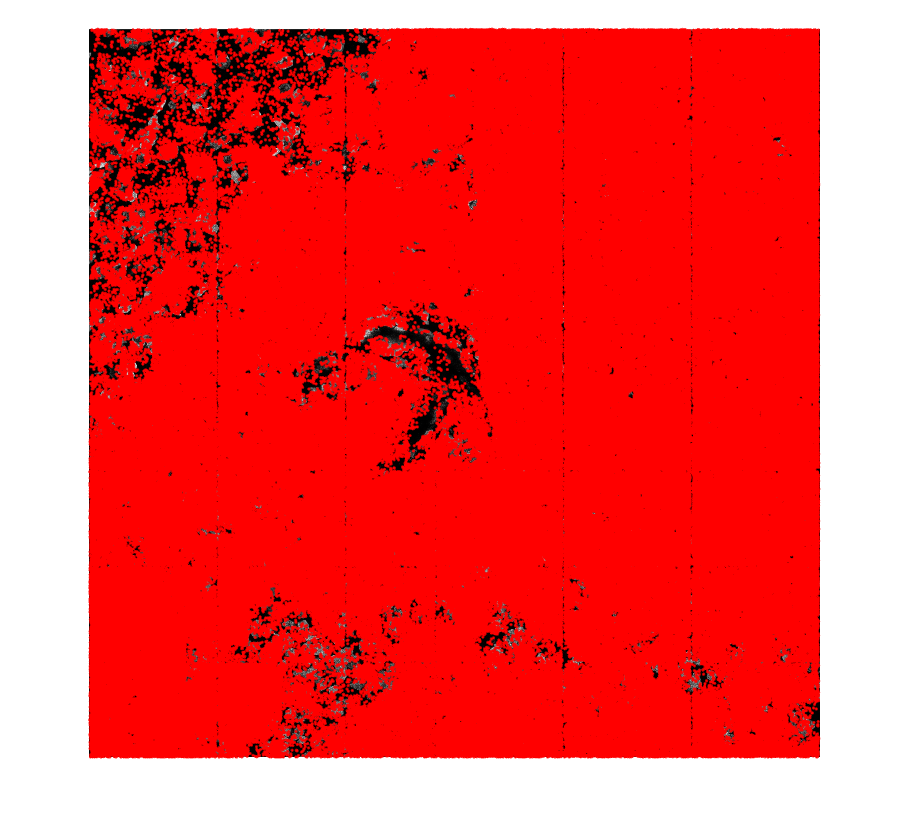

nissl_path = 'E:\Brain_slice_0302\nissl\nissl_max_stitched.tif';
nissl_img = imread(nissl_path);

figure
imshow(nissl_img)
hold on 
plot(merged_goodSpots(:,1), merged_goodSpots(:,2), '.', "Color", 'red', "MarkerSize", 5)
%plot(all_goodSpots(:,1), all_goodSpots(:,2), 'ro', "Color", 'red', "MarkerSize", 0.5)
hold off